%% SISTEMA DE CONTROL AVANZADO MYCOBOT
% Integra: ROS 2 (Hardware) + URDF (Modelo) + Planificación Continua

%% 1. Inicialización del Sistema
clear classes; clc;


% A) Conectar Hardware
try
    robot_hw = erobotics_interface();
    pause(1); % Dar tiempo a recibir el primer mensaje de /joint_states
catch
    warning('ROS 2 no detectado. Modo SIMULACIÓN.');
    robot_hw = [];
end

--- Iniciando Hardware MyCobot ---
 [tf_monitor] Listo para visualizar.
 ¡CONEXIÓN ESTABLECIDA con el Robot!



% B) Cargar Modelo
robot_model = MyCobotModel(); 

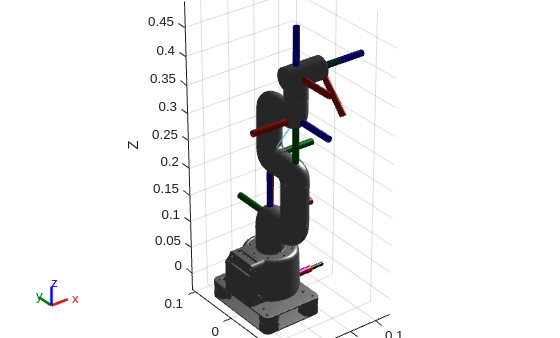


% C) Iniciar Planificador
planner = TrajectoryPlanner(robot_hw, robot_model);

Sincronizando con el robot real...


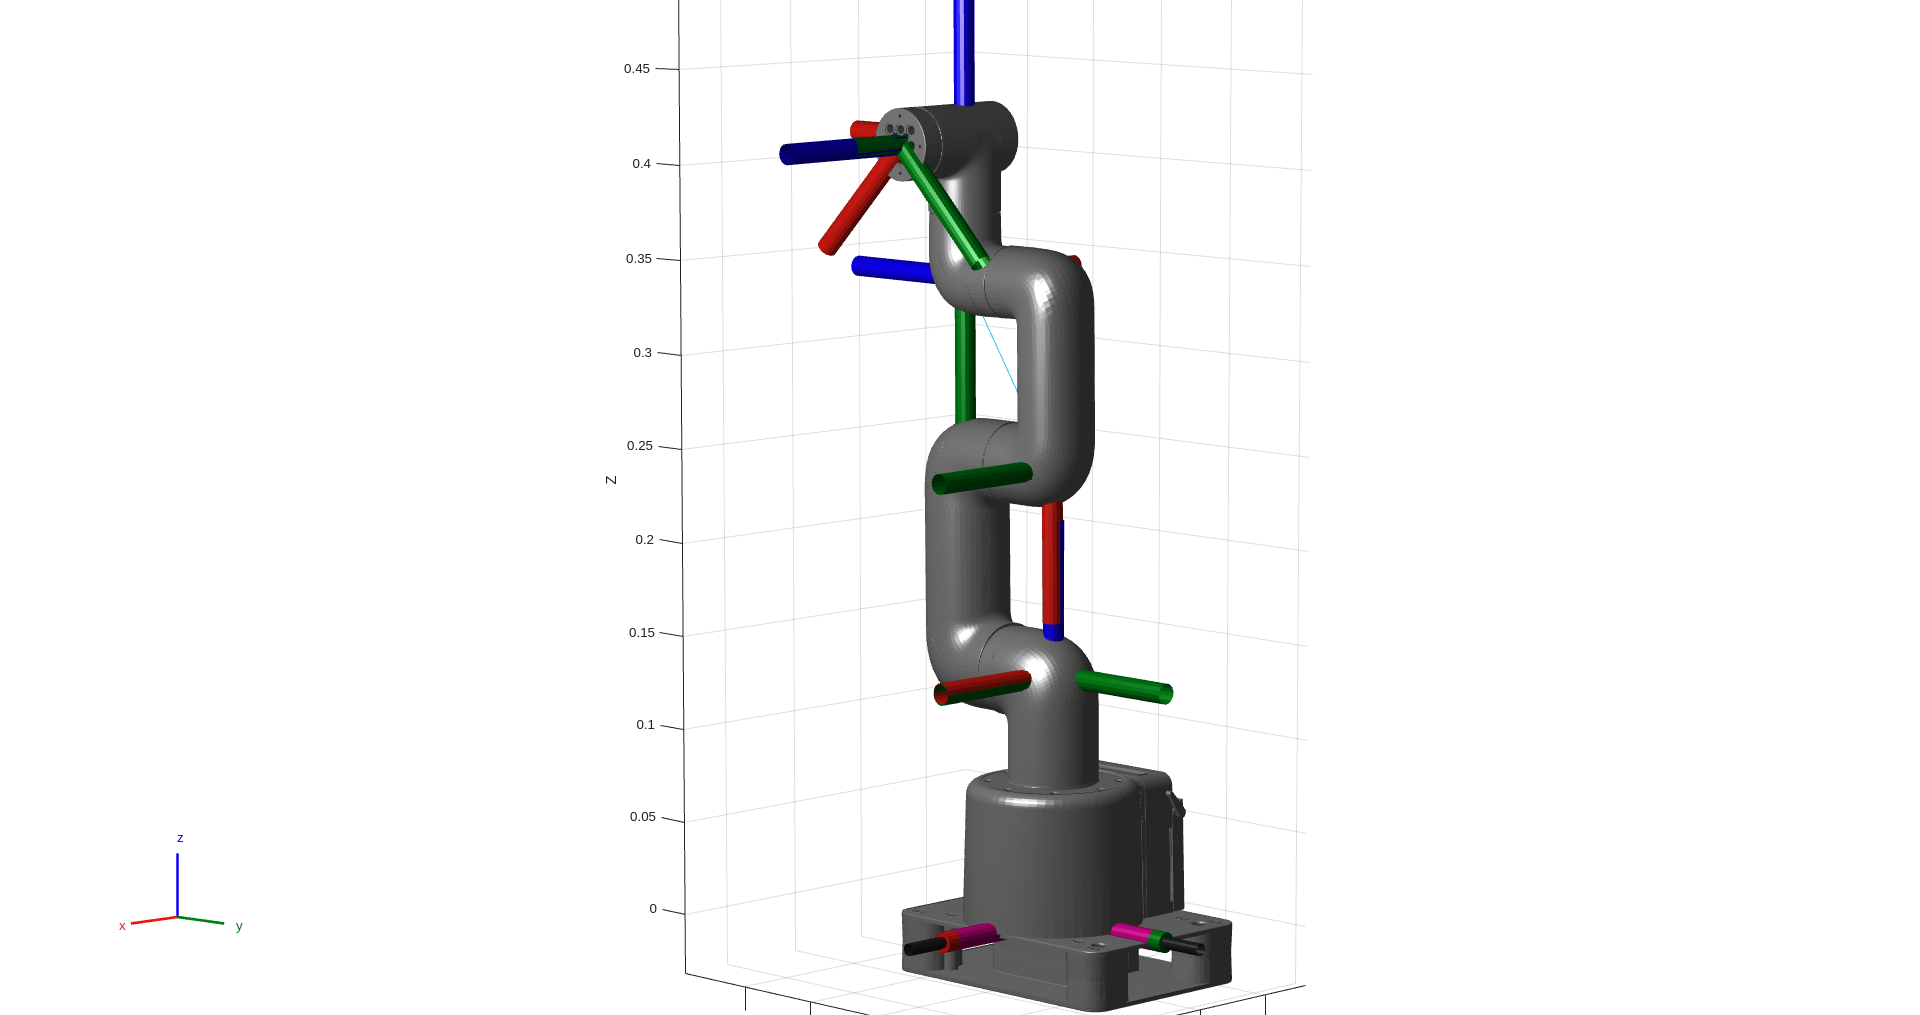


% D) Visualización Inicial (Estado Real)
if ~isempty(robot_hw)
    disp('Sincronizando con el robot real...');
    planner.sincronizarConHardware();
end


disp('Sistema listo.');

Sistema listo.



%% 2. Control Cartesiano (Desde posición actual)
% El robot partirá de donde esté ahora mismo (leído por sensores)
% hacia la nueva coordenada.

x = 0.22; 
y = -0.10; 
z = 0.22;

% Orientación (Radianes)
roll = 0; pitch = 0; yaw = 0;

tiempo = 4.0; 

planner.moverCartesiano(x, y, z, roll, pitch, yaw, tiempo);

Planificando ruta a: [0.22 -0.10 0.22]...


Error using quinticpolytraj (line 91)
The timePoints and wayPoints inputs must have the same number of columns.

Error in TrajectoryPlanner/ejecutarTrayectoria (line 72)
            [qMatrix, ~, ~] = quinticpolytraj([qStart; qEnd]', [0, tiempoTotal], t);
            ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^
Error in 


%% 3. Secuencia de Movimientos
% Gracias a la lectura de estado, cada movimiento empieza exactamente
% donde terminó el anterior, eliminando saltos.

puntos = [
    0.20,  0.15, 0.25;  
    0.20, -0.15, 0.25;  
    0.25,  0.00, 0.20;  
];

for i = 1:size(puntos, 1)
    pt = puntos(i,:);
    fprintf('Planificando hacia punto %d...\n', i);
    
    % Sincronizar visualización por si hubo error o deriva
    planner.sincronizarConHardware();
    
    planner.moverCartesiano(pt(1), pt(2), pt(3), 0, 0, 0, 3.0);
    
    pause(3.5); 
end

%% 4. Vuelta a Casa
planner.irAHome();